# The Assignment Model

The classical assignment model deals with matching workers (with varying skills) to jobs. Presumably, skill variation affects the cost of completing a job. The goal is to determine the minimum cost assignment of workers to jobs. The general assignment model with $n$ workers and $n$ jobs is represented in **Table 1**. The element $c_{ij}$ represents the cost of assigning worker $i$ to job $j$.There is no loss of generality in assuming that the number of workers and the number of jobs are equal, because we can always add fictitious workers or fictitious jobs to satisfy this assumption. 

The assignment model is a special case of the transportation model where workers represent sources and jobs represent destinations. The supply (demand) amount at each source (destination) exactly equals 1. The cost of “transporting” worker $i$ to job $j$ is $c_{ij}$. In effect, the assignment model can be solved directly as a regular transportation model (or as a regular LP).

**Table 1: **Assignment Model

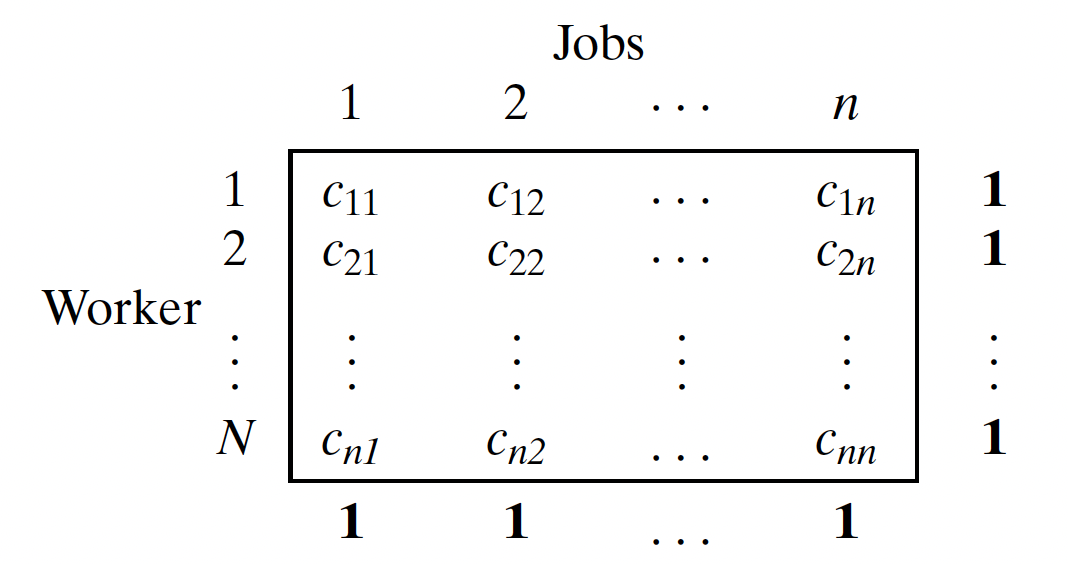

## **Example 1:** Klyne’s Assignment Problem

Joe Klyne’s three children, John, Karen, and Terri, want to earn some money for personal expenses. Mr. Klyne has chosen three chores for his children: mowing the lawn, painting the garage door, and washing the family cars. To avoid anticipated sibling competition, he asks them to submit individual (secret) bids for what they feel is fair pay for each of the three chores. **Table 1** summarizes the bids received. The children will abide by their father’s decision regarding the assignment of chores.

**Table 1: **Klyne’s Assignment Problem

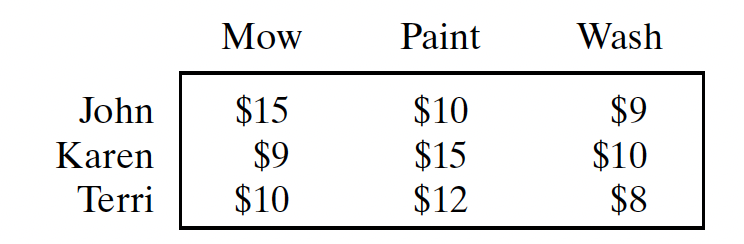

Optimum solution:

John gets the paint job, Karen gets to mow the lawn, and Terri gets to wash the family cars. The total cost to Mr. Klyne is 9 + 10 + 8 = $27.

% Example 1 (LP)

f1   = [15; 10; 9; 9; 15; 10; 10; 12;  8];
A1   = [1	1	1	0	0	0	0	0	0;
        0	0	0	1	1	1	0	0	0;
        0	0	0	0	0	0	1	1	1];
Aeq1 = [1	0	0	1	0	0	1	0	0;
        0	1	0	0	1	0	0	1	0;
        0	0	1	0	0	1	0	0	1];
b1   = [1; 1; 1];
beq1 = [1; 1; 1];
lb1  = zeros(9,1);
ub1  = [];

[x1, fval1, exitflag1, output1, lambda1] = linprog(f1, A1, b1, Aeq1, beq1, lb1, ub1);


Optimal solution found.




% Display the results of the optimization
disp('Optimal solution (x1):');

Optimal solution (x1):


disp(x1);

     0
     1
     0
     1
     0
     0
     0
     0
     1



disp('Minimum assignment cost (fval1):');

Minimum assignment cost (fval1):


disp(fval1);

    27



# matchpairs

Solve linear assignment problem

## Syntax

`M = matchpairs(Cost,costUnmatched)`

`[M,uR,uC] = matchpairs(Cost,costUnmatched)`

`[``___``] = matchpairs(Cost,costUnmatched,goal)`

## Description

`M ``= matchpairs(Cost,costUnmatched)` solves the **linear assignment problem** for the rows and columns of the matrix `Cost`. Each row is assigned to a column in such a way that the total cost is minimized. `costUnmatched` specifies the cost per row of not assigning each row, and also the cost per column of not having a row assigned to each column.

`[M,uR,uC] = matchpairs(Cost,costUnmatched)` additionally returns indices for unmatched rows in `uR` and indices for unmatched columns in `uC`.

`[___] = matchpairs(Cost,costUnmatched,goal)` specifies the goal of the optimization using any of the output argument combinations in previous syntaxes. `goal` can be `'min'` or `'max'` to produce matches that either minimize or maximize the total cost.

# Linear Assignment Problem

The *linear assignment problem* is a way of assigning rows to columns such that each row is assigned to a column and the total cost of the assignments is minimized (or maximized). The cost of assigning each row to each column is captured in a *cost matrix*. The entry `Cost(i,j)` is the cost of assigning row `i` to column `j`.

The *cost of unassignment* assigns a cost to any row or column that is not matched. This practice allows for minimum-cost solutions that do not assign all rows or columns. If a row and column are not matched, this increases the total cost by `2*costUnmatched`.

The total cost of a solution `M` is the sum of the cost of all matched pairs added to the cost of all unmatched pairs:


$$\textrm{TC}=\sum_{i=1}^p \textrm{Cost}\left(M\left(i,1\right),M\left(i,2\right)\right)+\textrm{costUnmatched}\cdot \left(m+n-2p\right)$$


In code the total cost is

`CostAssigned = sum(Cost(sub2ind(size(Cost), M(:,1), M(:,2))));`

`CostUnassigned = costUnmatched*(sum(size(Cost))-2*size(M,1));`

`TotalCost = CostAssigned + CostUnassigned;`

`Cost` is an `m-by-n` matrix.

`M` is a `p-by-2` matrix, where `M(i,1)` and `M(i,2)` are the row and column of a matched pair.

`m+n-2*p` is the total number of *unmatched* rows and columns.

## **Example 2:** Klyne’s Assignment Problem (revisited)

Use `matchpairs` to assign the chores to three children with minimal cost. 

% Example 2 (matchpairs)

C1  = [15  10   9;
        9  15  10;
       10  12   8];
M1 = matchpairs(C1,100);
TotalCost1 = sum(C1(sub2ind(size(C1), M1(:,1), M1(:,2))));

% Display the results of the optimization
disp('Optimal solution (M1):');

Optimal solution (M1):


disp(M1);

     2     1
     1     2
     3     3



disp('Minimum assignment cost (TotalCost1):');

Minimum assignment cost (TotalCost1):


disp(TotalCost1);

    27



## Example 3: Assign Flights with Minimal Cost

Assign salespeople to flights such that the total cost of transportation is minimized.

A company has four salespeople who need to travel to key cities around the country. The company must book their flights, and wants to spend as little money as possible. These salespeople are based in different parts of the country, so the cost for them to fly to each city varies.

This table shows the cost for each salesperson to fly to each key city.

Each city represents a sales opportunity. If a city is missed, then the company loses out on an average revenue gain of $2,000.

% Example 3

% Create a cost matrix to represent the cost of each salesperson flying to each city.
C2 = [600 670 960 560
      900 280 970 540
      310 350 950 820
      325 290 600 540];

% Use matchpairs to assign the salespeople to the cities with minimal cost. 
% Specify the cost of unassignment as 1000, since the cost of unassignment 
% is counted twice if a row and a column remain unmatched.
M2 = matchpairs(C2,1000);

TotalCost2 = sum(C2(sub2ind(size(C2), M2(:,1), M2(:,2))));

% Display the results of the optimization
disp('Optimal solution (M2):');

Optimal solution (M2):


disp(M2);

     3     1
     2     2
     4     3
     1     4



disp('Minimum assignment cost (TotalCost2):');

Minimum assignment cost (TotalCost2):


disp(TotalCost2);

        1750



## Example 4: Unequal Numbers of Rows and Columns

Match rows to columns when you have many more columns than rows in the cost matrix.

Create a 3-by-8 cost matrix. Since you have only three rows, `matchpairs` can produce at most three matches with the eight columns.

rng default % for reproducibility
C3 = randi([10 100], 3, 8)

C3 =     84    93    35    97    97    22    82    13
    92    67    59    24    54    48    97    87
    21    18    97    98    82    93    69    94


Use `matchpairs` to match the rows and columns of the cost matrix. To get the maximum number of matches, use a large cost of unassignment (relative to the magnitude of the entries in the cost matrix). Specify three outputs to return the indices of unmatched rows and columns.

% Example 4

umCost = 1000;

[M3,uR3,uC3] = matchpairs(C3,umCost);

TotalCost3 = sum(C3(sub2ind(size(C3), M3(:,1), M3(:,2)))) + ...
    umCost*(size(C3,1)+size(C3,2)-2*size(M3,1));

% Display the results of the optimization
disp('Optimal solution (M3):');

Optimal solution (M3):


disp(M3);

     3     2
     2     4
     1     8



disp('Minimum assignment cost (TotalCost3):');

Minimum assignment cost (TotalCost3):


disp(TotalCost3);

        5055



disp('Unmatched row (uR3):');

Unmatched row (uR3):


disp(uR3);
disp('Unmatched column (uC3):');

Unmatched column (uC3):


disp(uC3);

     1
     3
     5
     6
     7



## Example 5: Assign Taxis to Maximize Profit

Assign taxis to routes such that the profit is maximized.

A taxi company has several ride requests from across the city. The company wants to dispatch its limited number of taxis in a way that makes the most money.

**Table 2 **shows the estimated taxi fare for each of five ride requests. Only three of the five ride requests can be filled.

**Table 2: **Estimated taxi fare for each ride request

Create a profits matrix to represent the profits of each taxi ride.

P = [5.7 6.3 3.1 4.8 3.5
     5.8 6.4 3.3 4.7 3.2
     5.7 6.3 3.2 4.9 3.4];

Use `matchpairs` to match the taxis to the most profitable rides. Specify three outputs to return any unmatched rows and columns, and the `'max'` option to maximize the profits. Specify the cost of unassignment as zero, since the company makes no money from unfilled taxis or ride requests.

% Example 5

costUnmatched = 0;
[M4,uR4,uC4] = matchpairs(P,costUnmatched,'max')

M4 =      1     1
     2     2
     3     4



uR4 =

  0×1 empty double column vector



uC4 =      3
     5



% Calculate the total profits for the calculated solution. 
% Since costUnmatched is zero, you only need to add together the profits from each match.

TotalProfits = sum(P(sub2ind(size(P), M4(:,1), M4(:,2))))

TotalProfits = 17


% Display the results of the optimization
disp('Optimal solution (M4):');

Optimal solution (M4):


disp(M4);

     1     1
     2     2
     3     4



disp('Maximum assignment profit (TotalProfits):');

Maximum assignment profit (TotalProfits):


disp(TotalProfits);

    17



disp('Unmatched row (uR4):');

Unmatched row (uR4):


disp(uR4);
disp('Unmatched column (uC4):');

Unmatched column (uC4):


disp(uC4);

     3
     5



# Practice

## Question 1

**Figure 1** gives a schematic layout of a machine shop with its existing work centers designated by squares 1, 2, 3, and 4. Four new work centers, I, II, III, and IV, are to be added to the shop at the locations designated by circles a, b, c, and d. The objective is to assign the new centers to the proposed locations to minimize the total materials handling traffic between the existing centers and the proposed ones. **Table 3** summarizes the frequency of trips between the new centers and the old ones. Materials handling equipment travels along the rectangular aisles intersecting at the locations of the centers. For example, the one-way travel distance (in meters) between center 1 and location b is 30 + 20 = 50 m.

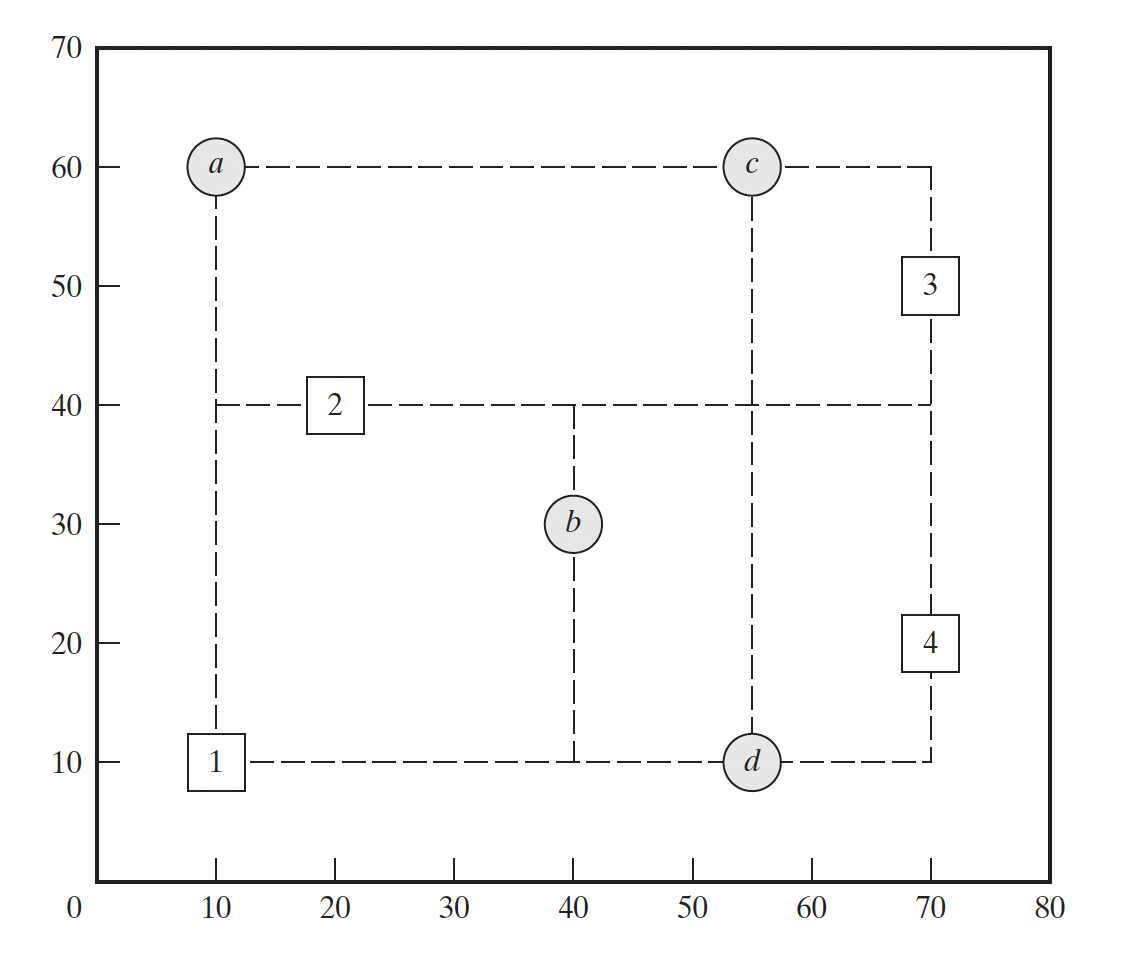

**Figure 1:** Machine shop layout

**Table 3: **The frequency of trips between the new centers and the old ones.

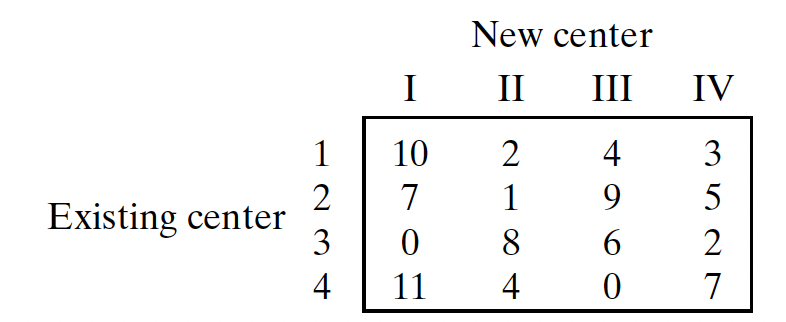

% Question 1


cost =         1810        1370        1940        1180
        1090         770         665         695
         890         770        1025        1095
        1140         820         995         745


Optimal solution (M):


     3     1
     4     2
     2     3
     1     4



Minimum assignment cost (TotalCost3):


        3555



Unmatched row (uR3):


Unmatched column (uC3):


## Question 2

JoShop needs to assign four jobs to four workers. The cost of performing a job is a function of the skills of the workers. **Table 4 **summarizes the cost of the assignments. Worker 1 cannot do job 3, and worker 3 cannot do job 4. 

**Table 4: **The cost of the assignments for JoShop

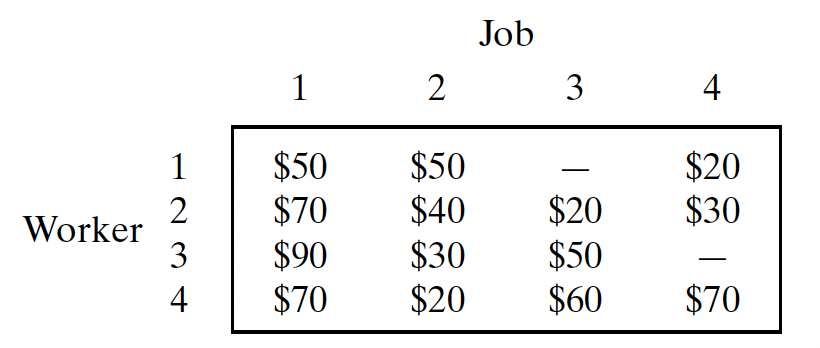

- Determine the optimal assignment.

- Suppose that an additional (fifth) worker becomes available for performing the four jobs at the respective costs of $60, $45, $30, and $80. Is it economical to replace one of the current four workers with the new one?

% Question 2



`End-of-file`

`Pongsun B.`

`2025-10-09`